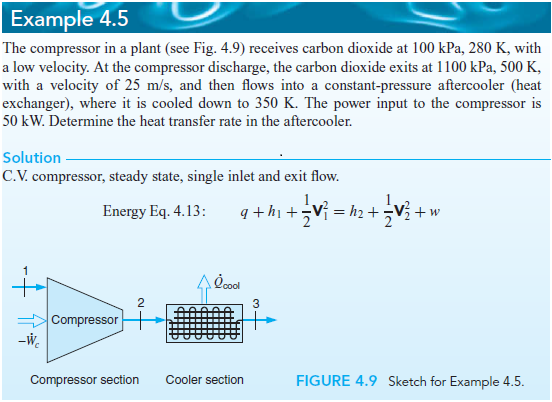

# class

u = symunit;

# state 1

% -------------------
% given
p1 = 100*u.kPa;
T1 = 280*u.K;
V1 = 0;
% -------------------
% specific enthalpy
h1 = interp1([250 300], [173.44 214.38], double(removeUnits(T1)))*u.kJ/u.kg;
% -------------------

# state 2

% -------------------
% given
p2 = 1100*u.kPa;
T2 = 500*u.K;
V2 = 25*u.m/u.s;
% -------------------
% specific enthalpy
h2 = 401.52*u.kJ/u.kg;
% -------------------

# state 3

% -------------------
% given
p3 = 1100*u.kPa;
T3 = 350*u.K;
V3 = 25*u.m/u.s;
% -------------------
% specific enthalpy
h3 = 257.90*u.kJ/u.kg;
% -------------------

# first law of thermodynamics (compressor)

syms mdot;
Qdot_12 = 0;
Wdot_12 = -50*u.kW;
mdot = simplify(solve(Qdot_12+mdot*(h1+V1^2/2) == mdot*(h2+V2^2/2)+Wdot_12));
mdot_vpa = vpa(mdot, 3) %#ok

$$mdot\_vpa = 0.245\,\frac{\mathrm{kg}}{s}$$

clear mdot_vpa;

# first law of thermodynamics (cooler)

syms Qdot_23;
Wdot_23 = 0;
Qdot_23 = rewrite(solve(Qdot_23+mdot*(h2+V2^2/2) == mdot*(h3+V3^2/2)+Wdot_23), u.kW);
Qdot_23_vpa = vpa(Qdot_23, 4) %#ok

$$Qdot\_23\_vpa = -35.23\,\mathrm{kW}$$

clear Qdot_23_vpa;